Analysis of Data collected on 2021/09/30:

Three set of data obtained:

Dataset            File Name                                Details

1                      Tx1Rx1_T-mid_R1-L                Left Antenna = Rx1; Mid Antenna = Tx1; Right Antenna = NA; plate @ 45 cm

2                      Tx1Rx1_T-L_R1-mid                Left Antenna = Tx1; Mid Antenna = Rx1; Right Antenna = NA; plate @ 45 cm

3                      Tx1Rx1_T-L_R1-mid_plate2    Left Antenna = Tx1; Mid Antenna = Rx1; Right Antenna = NA; plate @ 75 cm

Objectives:

    1. Compare datasets 1 and 2 to verify whether antennas are identical.

    2. Compare datasets 2 and 3 to verify range calculation.

% Set up:
clear all
clc
dataDir = "../Data/2021-09-30"

dataDir = "../Data/2021-09-30"

% Analysis of dataset-1
fname1 = "Tx1Rx1_T-mid_R1-L.mat";
dataset = load_ancortek_data(fullfile(dataDir, fname1));
props = dataset.props;  % signal and radar properties.
datamat = dataset.datamatrix;  % datacube of shape (nCh, nPules, nRanges).

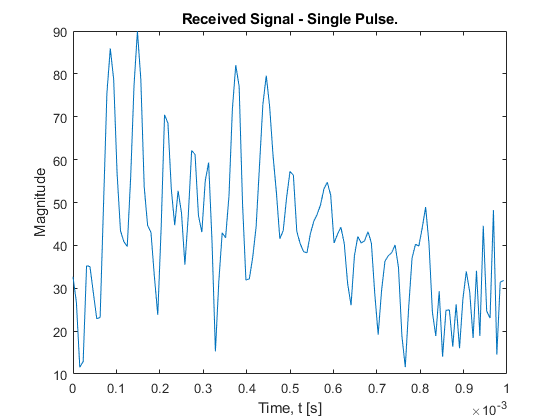

% Analyzing a single pulse
signalRx1 = squeeze(datamat(1, 1, :));
tmax = props.SweepTime;
fs = props.SamplingRate;
dt = 1/fs;
t = 0:dt:tmax-dt;

fc = props.f0;
BW = props.BW;
fslope = props.fslope;

figure
plot(t, abs(signalRx1));
xlabel("Time, t [s]")
ylabel("Magnitude")
title("Received Signal - Single Pulse.")

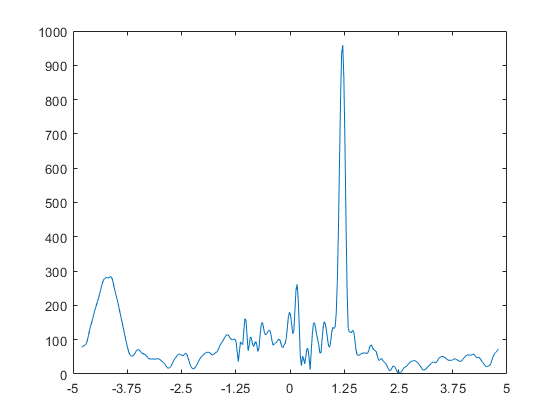

% signalTx = rectangularPulse(0, dt, t/dt).*exp(1j*2*pi*(fc - 0.5*BW + 0.5*fslope*t).*t);
% y = fliplr(signalTx);
% Y = conj(fft(y));
% X = fft(signalRx1);
% M = X'.*Y;
% f = -fs/2:1/(tmax-dt):fs/2;
% 
% figure
% plot(f, abs(fftshift(M)))

signalRx1_zpadded = [signalRx1;  zeros([2*length(signalRx1), 1])];
f = linspace(-fs/2, fs/2, length(signalRx1_zpadded));
r = (0.5*3e8/fslope) * f;
X = fft(signalRx1_zpadded.*hann(length(signalRx1_zpadded)));

figure
plot(r, abs(fftshift(X)));
xticks(linspace(-5, 5, 9));

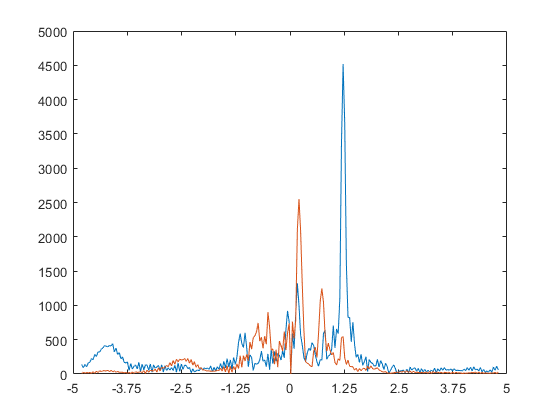

datamat_zeropadded = cat(3, datamat, zeros(size(datamat)));
X2 = fft(datamat_zeropadded, size(datamat_zeropadded, 3), 3);
X2_pulseavgd = squeeze(mean(X2, 2));
f = linspace(-fs/2, fs/2, length(X2_pulseavgd));
r = (0.5*3e8/fslope) * f;

figure
plot(r, abs(fftshift(X2_pulseavgd(1, :))), r, abs(fftshift(X2_pulseavgd(2, :))));
xticks(linspace(-5, 5, 9));